# Leitor de arquivo no formato CRFS BIN.

Trata-se de leitor dos principais tipos de dados relacionados às versões 3, 4 e 5 de arquivo no formato CRFS BIN, gerado originalmente pela aplicação Logger, do RFeye.

Versão: **19/05/2021**

function specData = FileReader_CRFSBin(filename, ReadType, metaData)

    arguments
        filename char
        ReadType char   = 'SingleFile'
        metaData struct = []
    end
    
    global SpecInfo
    
    fileID = fopen(filename);
    if fileID == -1; error('Arquivo não encontrado!');
    end
    
    Format = fread(fileID, 1, 'int32', 32);
    switch Format
        case 21;   FileFormat = 'CRFS Bin v.3'; % Engloba também o 'CRFS Bin v.2' (DataTypes 4, 7, 8 etc)
        case 22;   FileFormat = 'CRFS Bin v.4';
        case 23;   FileFormat = 'CRFS Bin v.5';
        otherwise; error('Parece não se tratar de um arquivo no formato CRFS Bin (v.3-5).')
    end
    
    switch ReadType
        case {'MetaData', 'SingleFile'}
            SpecInfo = struct('Node',        '', 'ThreadID',  '', 'MetaData',        [], 'Samples',   [], ...
                              'Data',        {}, 'statsData', [], 'FileFormat',      '', 'TaskName',  '', ...
                              'Description', '', 'gps',       [], 'ObservationTime', '', 'Blocks',    []);
            
            Fcn_MetaDataReader(fileID, FileFormat);
            
            if strcmp(ReadType, 'SingleFile')
                Fcn_SpecDataReader(fileID)
            end
            
        case 'SpecData'
            SpecInfo = metaData(1).Data;
            Fcn_SpecDataReader(fileID);
    end
    fclose(fileID);
    
    specData = SpecInfo;
    clear global SpecInfo
end

Leitura de **metadados**.

function Fcn_MetaDataReader(fileID, FileFormat)

    global SpecInfo
    
    auxStrCell = {};
    Hostname   = '';
    GPS        = struct('Status', 0, 'Latitude', -1, 'Longitude', -1, 'Location', ''); % Status: 0 (inválido), > 0 (válido)
    gpsSamples = 0;
    
    fseek(fileID, 0, 'eof');
    fileSize = ftell(fileID);
    fseek(fileID, 36, 'bof');
    
    ii = 0;
    while ~feof(fileID)
        ThreadID   = fread(fileID, 1, 'uint32');
        BytesBlock = fread(fileID, 1, 'uint32');
        DataType   = fread(fileID, 1,  'int32');
        
        if fileSize-ftell(fileID) < BytesBlock+8
            break
        end
        
        if ~isempty(DataType)
            switch DataType
                case 3
                    Read_DataType3(fileID, BytesBlock);
                    
                case 21
                    [Hostname, ~, TaskName, ~] = Read_DataType21(fileID, BytesBlock);
                    
                case {22, 24}
                    ii = ii+1;
                    if DataType == 22;     Description  = Read_DataType22(fileID, BytesBlock);
                    else                 ; [~, Description] = Read_DataType24(fileID, BytesBlock);
                    end
                    auxStrCell(ii, 1:2) = {ThreadID, Description};
                    
                case 40
                    [~, auxGPS] = Read_DataType40(fileID, BytesBlock);
                    
                    if auxGPS.Status
                        gpsSamples = gpsSamples+1;
                        if gpsSamples == 1
                            GPS        = auxGPS;
                            GPS.Status = 1;
                        else
                            GPS.Latitude   = GPS.Latitude  + auxGPS.Latitude;
                            GPS.Longitude  = GPS.Longitude + auxGPS.Longitude;
                        end
                    end
                    
                case 41
                    Read_DataType41(fileID, BytesBlock);
                    
                case 42
                    Read_DataType42(fileID, BytesBlock);
                    
                case {60, 61, 62, 63, 64, 65, 67, 68, 69}
                    switch DataType
                        case 60; Read_DataType60(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 61; Read_DataType61(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 62; Read_DataType62(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 63; Read_DataType63(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 64; Read_DataType64(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 65; Read_DataType65(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 67; Read_DataType67(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 68; Read_DataType68(fileID, 0, [ThreadID, BytesBlock, DataType]);
                        case 69; Read_DataType69(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    end
                    
                otherwise
                    warning(['DataType ' num2str(DataType) ' pendente de implementação. Favor acionar o servidor Eric (GR08).']);
                    Read_CheckSum(fileID, BytesBlock)
                    fseek(fileID, BytesBlock, 'cof');
            end
            Read_DataBlockTrailer(fileID);
        end
    end
    
    if gpsSamples
        GPS.Latitude  = GPS.Latitude  / (gpsSamples * 1e+6);
        GPS.Longitude = GPS.Longitude / (gpsSamples * 1e+6);
        GPS.Location  = FindCity(GPS);
    end
    
    auxRows = size(auxStrCell, 1);
    for jj = auxRows:-1:1
        if ~ismember(auxStrCell{jj,1}, [SpecInfo.ThreadID])
           auxStrCell(jj,:) = [];
        end
    end
    auxStrCell = sortrows(auxStrCell);
    
    [~, auxIndex] = sort([SpecInfo.ThreadID]);
    SpecInfo = SpecInfo(auxIndex);
    
    if ~isempty(SpecInfo)
        ObservationTime = Read_ObservationTime(fileID);
    end    

    for kk = 1:numel(SpecInfo)
        SpecInfo(kk).Node            = Hostname;
        SpecInfo(kk).FileFormat      = FileFormat;
        SpecInfo(kk).TaskName        = TaskName;
        SpecInfo(kk).ObservationTime = ObservationTime;
        
        %% String com alguns dos metadados p/ simplificar leitura no app.
        %% Unidade
        switch SpecInfo(kk).MetaData.LevelUnit
            case 0; SpecInfo(kk).MetaData.LevelUnit = 1; Unit = 'dBm';
            case 1; SpecInfo(kk).MetaData.LevelUnit = 3; Unit = 'dBμV/m';
        end
        
        %% Resolução
        if SpecInfo(kk).MetaData.Resolution == -1
            SpecInfo(kk).MetaData.Resolution = [];
        end
        
        Resolution = '';
        if ~isempty(SpecInfo(kk).MetaData.Resolution)
            Resolution = sprintf('%.3f kHz', SpecInfo(kk).MetaData.Resolution/1000);
        end
        
        %% SampleTime (SweepTime/ProcessingTime/IntegrationTime)
        if ~isempty(SpecInfo(kk).MetaData.SampleTime)
            SpecInfo(kk).MetaData.SampleTime = SpecInfo(kk).MetaData.SampleTime / SpecInfo(kk).Samples;
        end
        
        %% Processamento do traço.
        traceMode = '';
        if ismember(SpecInfo(kk).MetaData.DataType, [62, 65, 69])
            traceMode = 'OCC';
        else
            switch SpecInfo(kk).MetaData.TraceMode
                case 0; traceMode = 'Single Measurement';
                case 1; traceMode = 'Mean';
                case 2; traceMode = 'Peak';
                case 3; traceMode = 'Minimum';
            end
        end

        %% Detector
        Detector = '';
        
        %% Antena.
        antennaName = '';
        if ~isempty(SpecInfo(kk).MetaData.Antenna)
            switch SpecInfo(kk).MetaData.Antenna
                case 0; antennaName = 'CRFS RFeye (Auto)';
                case 1; antennaName = 'CRFS RFeye Port 1';
                case 2; antennaName = 'CRFS RFeye Port 2';
                case 3; antennaName = 'CRFS RFeye Port 3';
                case 4; antennaName = 'CRFS RFeye Port 4';
            end
        end
        
        SpecInfo(kk).MetaData.metaString = {Unit, Resolution, traceMode, Detector, antennaName};
        
        if ~isempty(auxStrCell)
            SpecInfo(kk).Description = auxStrCell{kk, 2};
        end
        
        SpecInfo(kk).gps = GPS;
    end
end

Leitura de informações de **níveis apenas dos dados de blocos espectrais (incluso ocupação)**.

Analisadas três opções de organização dos dados:

- Timetable. A mais bonita. A mais ineficiente. Leitura de arquivo de referência em 47 segundos.

- Cell array. DateStr e Matrix. A mais eficiente. Perde o datetimeruler no plot (e os filtros de timestamp). Necessário organizar como "yyyy/mm/dd HH:MM:SS" para possibilitar ordenação. Leitura de arquivo de referência em 5 segundos.

- Cell array. DateTime e Matrix. Leitura de arquivo de referência em 8 segundos.

function Fcn_SpecDataReader(fileID)

    global SpecInfo
    
    for ii = 1:length([SpecInfo.MetaData])
        SpecInfo(ii).Data  = {repmat(datetime([0 0 0 0 0 0], 'Format', 'dd/MM/yyyy HH:mm:ss'), 1, SpecInfo(ii).Samples), ...
                              zeros(SpecInfo(ii).MetaData.DataPoints, SpecInfo(ii).Samples, 'single')};

        for jj = 1:SpecInfo(ii).Samples
            switch SpecInfo(ii).MetaData.DataType
                case 60; Read_DataType60(fileID, 1, [], ii, jj);
                case 61; Read_DataType61(fileID, 1, [], ii, jj);
                case 62; Read_DataType62(fileID, 1, [], ii, jj);
                case 63; Read_DataType63(fileID, 1, [], ii, jj);
                case 64; Read_DataType64(fileID, 1, [], ii, jj);
                case 65; Read_DataType65(fileID, 1, [], ii, jj);
                case 67; Read_DataType67(fileID, 1, [], ii, jj);
                case 68; Read_DataType68(fileID, 1, [], ii, jj);
                case 69; Read_DataType69(fileID, 1, [], ii, jj);
            end
        end
    end

end

# Funções auxiliares

**CheckSum Read**

function Read_CheckSum(fileID, BytesBlock)
    
    global CheckSumAdd
    
    fseek(fileID, -12, 'cof');
    
    auxCheckSum = fread(fileID, BytesBlock+12, 'uint8');
    CheckSumAdd = uint32(sum(auxCheckSum));
    
    fseek(fileID, -BytesBlock, 'cof');
    
end

**Data Block Trailer**

function Read_DataBlockTrailer(fileID)

    global CheckSumAdd
    
    DBT_CheckSum  = fread(fileID, 1, 'uint32');
    DBT_EOFMarker = fread(fileID, [1, 4], '*char');
    
    if (DBT_CheckSum ~= CheckSumAdd) | ~strcmp(DBT_EOFMarker, 'UUUU')
        warning('Erro em validação do DataBlocoTrailer (CheckSum ou EOFMarker).');
    end
end

**Análise de erro global e identificação de fluxo.**

function Read_auxDataType(fileID, Bin, ThreadID, BytesBlock, Description)

    global SpecInfo
    
    auxIndex = find([SpecInfo.ThreadID] == ThreadID);
    for ii = auxIndex
        if isequal(rmfield(Bin, 'SampleTime'), rmfield(SpecInfo(ii).MetaData, 'SampleTime'))
            auxIndex = ii;
            break
        else
            auxIndex = [];
        end
    end
    
    if ~isempty(auxIndex)
        if SpecInfo(auxIndex).Samples == 65536
            return
        end
        
        SpecInfo(auxIndex).Samples = SpecInfo(auxIndex).Samples + 1;
        
        if ~isempty(Bin.SampleTime)
            SpecInfo(auxIndex).MetaData.SampleTime = SpecInfo(auxIndex).MetaData.SampleTime + Bin.SampleTime;
        end
        
    else
        auxIndex = length([SpecInfo.ThreadID]) + 1;
        
        SpecInfo(auxIndex).ThreadID = ThreadID;
        SpecInfo(auxIndex).MetaData = Bin;
        SpecInfo(auxIndex).Samples  = 1;
        
        if ~isempty(Bin.SampleTime)
            SpecInfo(auxIndex).MetaData.SampleTime = Bin.SampleTime;
        end
        
        SpecInfo(auxIndex).Blocks = zeros(1, 65536);
        
        if ~isempty(Description)
            SpecInfo(auxIndex).Description = Description;
        end
    end
    SpecInfo(auxIndex).Blocks(SpecInfo(auxIndex).Samples) = ftell(fileID) - BytesBlock;

end

**Observation time.**

function ObservationTime = Read_ObservationTime(fileID)

    global SpecInfo
    
    for ii = 1:numel(SpecInfo)
        SpecInfo(ii).Blocks(SpecInfo(ii).Blocks == 0) = [];
        
        if ii == 1
            Observation_Blocks = [SpecInfo(1).Blocks(1), SpecInfo(1).Blocks(end)];
        else
            if SpecInfo(ii).Blocks(1)   < Observation_Blocks(1); Observation_Blocks(1) = SpecInfo(ii).Blocks(1);
            end
            
            if SpecInfo(ii).Blocks(end) > Observation_Blocks(2); Observation_Blocks(2) = SpecInfo(ii).Blocks(end);
            end
        end
    end
    
    for ii = 1:2
        fseek(fileID, Observation_Blocks(ii), 'bof');
            
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1);
        
        strTime{ii}  = datestr(datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds]), 'dd/mm/yyyy HH:MM:SS');
    end
    
    ObservationTime = sprintf('%s - %s', strTime{1}, strTime{2});
    
end

# Tipos de dados.

A seguir é apresentada tabela com os tipos de dados gerados pelo RFEye Logger. A versão dos tipos de dados, diga-se, é indicada no início do *script* carregado no Logger, na forma "file_version = 5". E essa informação é recuperada logo no início do arquivo binário, nos campos "FH_Format" (número) e "FH_sFormat" (string), da seguinte forma: FH_Format = 21 (file_version = 3), 22 (file_version = 4) e 23 (file_version = 5).

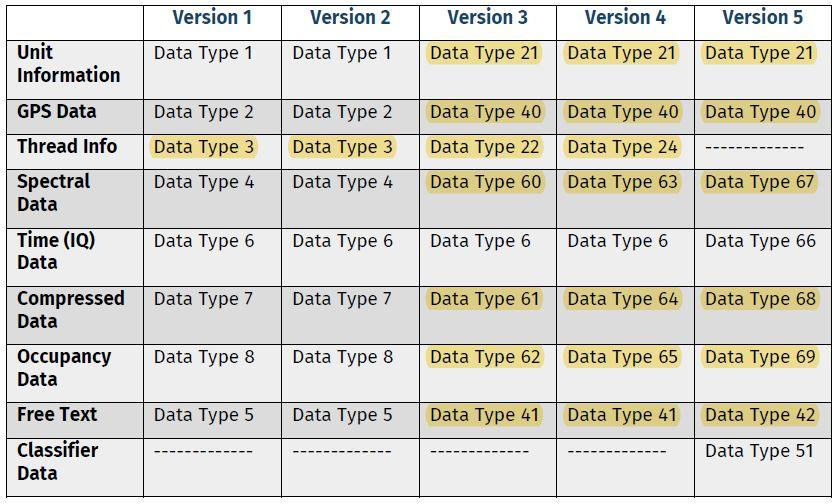

Em destaque os tipos de dados já implantados. 

**DataType 3**

function Text1 = Read_DataType3(fileID, BytesBlock)
    
    Read_CheckSum(fileID, BytesBlock);
    
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));
    
end

**DataType 21**

function [Hostname, Text1, Text2, FileNumber] = Read_DataType21(fileID, BytesBlock)
    
    Read_CheckSum(fileID, BytesBlock);
    
    Hostname      = deblank(fread(fileID, [1, 16], '*char'));
    Hostname(1:2) = upper(Hostname(1:2));
    Hostname      = erase(Hostname, '_');
    
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));  % unit_info = "Stationary" (ou "Mobile")
    Text1       = erase(Text1, '_');
    
    Text2Length = fread(fileID, 1, 'uint32');
    Text2       = deblank(fread(fileID, [1, Text2Length], '*char'));  % method = "ScriptRFeye2020_v.1"
    Text2       = erase(Text2, '_');
    
    FileNumber  = fread(fileID, 1, 'uint32');
    
end

**DataType 22**

Armazena o campo descrição de cada uma das funções _peak_ e _mean_.

function Text1 = Read_DataType22(fileID, BytesBlock)

    Read_CheckSum(fileID, BytesBlock);
    
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));  % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
    
end

**DataType 24**

function [GroupID, Text1] = Read_DataType24(fileID, BytesBlock)

    Read_CheckSum(fileID, BytesBlock);
    
    GroupID     = fread(fileID, 1, 'uint32');
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char')); % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
    
end

**DataType 40**

function [TimeStamp, GPS] = Read_DataType40(fileID, BytesBlock)
    
    TimeStamp = [];

    Read_CheckSum(fileID, BytesBlock);
    
    fseek(fileID, 20, 'cof');

%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 5);
%     
%     TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                           Time_Hours, Time_Minutes, Time_Seconds]);
    
%     Date_Day     = fread(fileID, 1);
%     Date_Month   = fread(fileID, 1);
%     Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 1);
%     
%     GPS.DateTime = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                              Time_Hours, Time_Minutes, Time_Seconds]);
                         
    GPS.Status     = fread(fileID, 1,  'uint8', 3);
%     GPS.Satellites = fread(fileID, 1,  'uint8');
%     GPS.Heading    = fread(fileID, 1, 'uint16');
    GPS.Latitude   = fread(fileID, 1,  'int32');
    GPS.Longitude  = fread(fileID, 1,  'int32', 8);
%     GPS.Speed      = fread(fileID, 1, 'uint32');
%     GPS.Altitude   = fread(fileID, 1, 'uint32');
    
end

**DataType 41**

function [TimeStamp, Identifier, Text1] = Read_DataType41(fileID, BytesBlock)
    
    TimeStamp = [];

    Read_CheckSum(fileID, BytesBlock);
    
    value1 = ftell(fileID);
    
    fseek(fileID, 12, 'cof');
%     % Data block
%     Date_Day   = fread(fileID, 1);
%     Date_Month = fread(fileID, 1);
%     Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
%     
%     Time_Hours   = fread(fileID, 1);
%     Time_Minutes = fread(fileID, 1);
%     Time_Seconds = fread(fileID, 1, 'uint8', 5);
%     
%     TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
%                           Time_Hours, Time_Minutes, Time_Seconds]);   % Em princípio: 2 blocos
                                                
    Identifier  = deblank(fread(fileID, [1, 32], '*char'));             % 'LOGGER_NAME', 'LOGGER_VERSION'
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));    % 'log_main   ', 'build_version=1.6.7;build_date=Oct  2 2018;build_time=09:11:30;'
    
    value2 = ftell(fileID);
    value2 = value2-value1;
    if value2 < BytesBlock
        fseek(fileID, BytesBlock-value2, 'cof');
    end
    
end

**DataType 42**

function [TimeStamp, GroupID, DynamicID, Identifier, Text1] = Read_DataType42(fileID, BytesBlock)
    
    Read_CheckSum(fileID, BytesBlock);
    
    value1 = ftell(fileID);
    
    Date_Day     = fread(fileID, 1);
    Date_Month   = fread(fileID, 1);
    Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;    
    Time_Hours   = fread(fileID, 1);
    Time_Minutes = fread(fileID, 1);
    Time_Seconds = fread(fileID, 1, 'uint8', 5);
    
    TimeStamp = datetime([Date_Year,  Date_Month,   Date_Day, ...
                          Time_Hours, Time_Minutes, Time_Seconds]);
    
    GroupID     = fread(fileID, 1, 'uint32');
    DynamicID   = fread(fileID, 1, 'uint32');                                
    Identifier  = deblank(fread(fileID, [1, 32], '*char'));                      % 'LOGGER_NAME', 'LOGGER_VERSION'
    Text1Length = fread(fileID, 1, 'uint32');
    Text1       = deblank(fread(fileID, [1, Text1Length], '*char'));             % 'log_main   ', 'build_version=1.6.7;build_date=Oct  2 2018;build_time=09:11:30;'
    
    value2 = ftell(fileID);
    value2 = value2-value1;
    if value2 < BytesBlock
        fseek(fileID, BytesBlock-value2, 'cof');
    end
    
end

**DataType 60**

function Read_DataType60(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.FreqStart  = auxF0 .* 10^expF0;
        Bin.FreqStop   = auxF1 .* 10^expF0;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        GERROR         = fread(fileID, 1,  'int8', 3);
        Bin.TraceMode  = fread(fileID, 1, 'uint8', 2); 
        NPAD           = fread(fileID, 1);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16', 2);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.DataPoints+NPAD, 'cof');

        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
    
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 21);
        
        OFFSET       = fread(fileID, 1, 'int8');
        NPAD         = fread(fileID, 1);
        NTUN         = fread(fileID, 1, 'uint16');
        NAGC         = fread(fileID, 1, 'uint16', 2);
        DataPoints   = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData    = fread(fileID, [DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 61**

function Read_DataType61(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.FreqStart  = auxF0 .* 10^expF0;
        Bin.FreqStop   = auxF1 .* 10^expF0;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        GERROR         = fread(fileID, 1,  'int8', 3);
        Bin.TraceMode  = fread(fileID, 1, 'uint8', 2); 
        NPAD           = fread(fileID, 1);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16', 2);
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.Threshold  = fread(fileID, 1, 'int32');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
    
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');

        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 21);
        
        OFFSET       = fread(fileID, 1, 'int8');
        NPAD         = fread(fileID, 1);
        NTUN         = fread(fileID, 1, 'uint16');
        NAGC         = fread(fileID, 1, 'uint16', 2);
        NCDATA       = fread(fileID, 1, 'uint32');
        THRESH       = fread(fileID, 1, 'int32');
        DataPoints   = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
        TraceData      = 2*((THRESH-1)-(OFFSET-127.5))*ones(DataPoints, 1, 'single');
        
        kk = 0;
        ll = 0;
        while kk < length(CompressedData)
            kk=kk+1;
            TraceValue = CompressedData(kk);
            
            if TraceValue == 255
                kk=kk+1;
                ll=ll+CompressedData(kk);
            else
                ll=ll+1;
                TraceData(ll,1) = TraceValue;
            end
        end
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = TraceData./2 + OFFSET - 127.5;
                
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 62**

function Read_DataType62(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.FreqStart  = auxF0 .* 10^expF0;
        Bin.FreqStop   = auxF1 .* 10^expF0;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        GERROR         = fread(fileID, 1,  'int8',  3);
        Bin.Threshold  = fread(fileID, 1,  'int16', 4);
        Bin.SampleTime = fread(fileID, 1, 'uint32');
        NPAD           = fread(fileID, 1, 'uint8', 3);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 29);
        
        NPAD         = fread(fileID, 1, 'uint8', 3);
        DataPoints   = fread(fileID, 1, 'uint32');
    
        TraceData    = fread(fileID, [DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
        
        fseek(fileID, NPAD, 'cof'); 
    end
    
end

**DataType 63**

function Read_DataType63(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo

    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32', 4);
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        Bin.SampleTime = fread(fileID, 1, 'uint32', 4) .* 1e-6;
        Bin.Antenna    = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.DataPoints+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')

    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        OFFSET       = fread(fileID, 1, 'int8', 3);
        NTUN         = fread(fileID, 1, 'uint16');
        NAGC         = fread(fileID, 1, 'uint16');
        NPAD         = fread(fileID, 1);
        DataPoints   = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData    = fread(fileID, [DataPoints, 1], 'uint8');

        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 64**

function Read_DataType64(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2))
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32', 4);
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        Bin.SampleTime = fread(fileID, 1, 'uint32', 4) .* 1e-6;
        Bin.Antenna    = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1, 'uint8');
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.Threshold  = fread(fileID, 1, 'int32');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day   = fread(fileID, 1);
        Date_Month = fread(fileID, 1);
        Date_Year  = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 32);
        
        OFFSET       = fread(fileID, 1, 'int8', 3);
        NTUN         = fread(fileID, 1, 'uint16');
        NAGC         = fread(fileID, 1, 'uint16');
        NPAD         = fread(fileID, 1);
        NCDATA       = fread(fileID, 1, 'uint32');
        THRESH       = fread(fileID, 1, 'int32');
        DataPoints   = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
        TraceData      = 2*((THRESH-1)-(OFFSET-127.5))*ones(DataPoints, 1, 'single');
        
        kk = 0;
        ll = 0;
        while kk < length(CompressedData)
            kk=kk+1;
            TraceValue = CompressedData(kk);
            
            if TraceValue == 255
                kk=kk+1;
                ll=ll+CompressedData(kk);
            else
                ll=ll+1;
                TraceData(ll,1) = TraceValue;
            end
        end
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = TraceData./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 65**

function Read_DataType65(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32', 8);
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        Bin.Antenna    = fread(fileID, 1, 'uint8', 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint16');
        GERROR         = fread(fileID, 1,  'int8', 2);
        NPAD           = fread(fileID, 1);     
        Bin.Threshold  = fread(fileID, 1,  'int16');
        Bin.SampleTime = fread(fileID, 1, 'uint16');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day       = fread(fileID, 1);
        Date_Month     = fread(fileID, 1);
        Date_Year      = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours     = fread(fileID, 1);
        Time_Minutes   = fread(fileID, 1);
        Time_Seconds   = fread(fileID, 1, 'uint8', 32);
        NPAD           = fread(fileID, 1, 'uint8', 4);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        TraceData      = fread(fileID, [Bin.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
            
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 67**

function Read_DataType67(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 20, 'cof');
        
        TextLength     = fread(fileID, 1, 'uint32');
        Description    = deblank(fread(fileID, [1, TextLength], '*char'));
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1,  'int32', 4);
        if Bin.Resolution == -1
            Bin.Resolution = [];                                        % Decodificação relacionada ao CRFS Bin gerado no appAnálise
        end
        
        Bin.SampleTime = fread(fileID, 1, 'uint32', 4) .* 1e-6;
        if Bin.SampleTime == 0
            Bin.SampleTime = [];                                        % Decodificação relacionada ao CRFS Bin gerado no appAnálise
        end
        
%       [run scan 0] 
%       scan = <interval>, <antenna>, <start>, <stop>, <resn_khz>, <repeats>, <decimate=3>, <reflev=4>, <agc=5>, <table=6>, <dBuVm=7>
%       repeats or DweelTime: 1 | 2 | 4 | 8 | 16 | 32
%       Não impacta nas operações de escrita. Pode ser que a razão de ser seja permanecer na faixa por
%       um tempo maior, avaliando rompimento de máscara ou algo assim.
%       repeats        = fread(fileID, 1, 'uint32');
        
        Bin.Antenna    = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        
%       GFLAGS         = fread(fileID, 1, 'int8');                      % -1
%       Reserved       = fread(fileID, 1);                              % 0
        
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.DataPoints+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), Description)
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        TextLength   = fread(fileID, 1, 'uint32');
        
        fseek(fileID,TextLength+31,'cof');
        
        OFFSET       = fread(fileID, 1, 'int8', 3);
        NTUN         = fread(fileID, 1, 'uint16');
        NAGC         = fread(fileID, 1, 'uint16');
        NPAD         = fread(fileID, 1);
        DataPoints   = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        TraceData    = fread(fileID, [DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2 + OFFSET - 127.5;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 68**

function Read_DataType68(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);

        fseek(fileID, 20, 'cof');
        
        TextLength     = fread(fileID, 1, 'uint32');
        Description    = deblank(fread(fileID, [1, TextLength], '*char'));
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        Bin.Resolution = fread(fileID, 1, 'uint32', 4);
        Bin.SampleTime = fread(fileID, 1, 'uint32', 4) .* 1e-6;
        Bin.Antenna    = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.Threshold  = fread(fileID, 1, 'int32');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), Description)
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        TextLength   = fread(fileID, 1, 'uint32');
        
        fseek(fileID,TextLength+31,'cof');
        
        OFFSET       = fread(fileID, 1, 'int8', 3);
        NTUN         = fread(fileID, 1, 'uint16');
        NAGC         = fread(fileID, 1, 'uint16');
        NPAD         = fread(fileID, 1);
        NCDATA       = fread(fileID, 1, 'uint32');
        THRESH       = fread(fileID, 1, 'int32');
        DataPoints   = fread(fileID, 1, 'uint32', 4*NTUN+NAGC);
        
        CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
        TraceData      = 2*((THRESH-1)-(OFFSET-127.5))*ones(DataPoints, 1, 'single');
        
        kk = 0;
        ll = 0;
        while kk < length(CompressedData)
            kk=kk+1;
            TraceValue = CompressedData(kk);
            
            if TraceValue == 255
                kk=kk+1;
                ll=ll+CompressedData(kk);
            else
                ll=ll+1;
                TraceData(ll,1) = TraceValue;
            end
        end
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = TraceData./2 + OFFSET - 127.5;

        fseek(fileID, NPAD, 'cof');
    end
    
end

**DataType 69**

function Read_DataType69(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);

        fseek(fileID, 20, 'cof');
      
        TextLength     = fread(fileID, 1, 'uint32');
        Description    = deblank(fread(fileID, [1, TextLength], '*char'));
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        
        Bin.Resolution = fread(fileID, 1, 'int32', 9);
        if Bin.Resolution == -1
            Bin.Resolution = [];                                        % Decodificação relacionada ao CRFS Bin gerado no appAnálise
        end
        
        Bin.Antenna    = fread(fileID, 1);                              % Erro na documentação (que incide no DataTools). PROC é, na verdade, ANTUID.
        Bin.LevelUnit  = fread(fileID, 1, 'uint16');
        GERROR         = fread(fileID, 1,  'int8', 2);
        NPAD           = fread(fileID, 1);      
        Bin.Threshold  = fread(fileID, 1,  'int16');
        Bin.SampleTime = fread(fileID, 1, 'uint16');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');
        
        if GERROR ~= -1
            warning('Código de erro global (GERROR).');
            return
        end
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), Description)
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        Date_Day     = fread(fileID, 1);
        Date_Month   = fread(fileID, 1);
        Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
        Time_Hours   = fread(fileID, 1);
        Time_Minutes = fread(fileID, 1);
        Time_Seconds = fread(fileID, 1, 'uint8', 13);
        TextLength   = fread(fileID, 1, 'uint32');
        
        fseek(fileID, TextLength+31,'cof');
        
        NPAD         = fread(fileID, 1, 'uint8', 4);      
        DataPoints   = fread(fileID, 1, 'uint32');
        TraceData    = fread(fileID, [DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, Time_Seconds], 'Format', 'dd/MM/yyyy HH:mm:ss');
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
        
        fseek(fileID, NPAD, 'cof');
    end
    
end